# Laboratorium 11

Karolina Piotrowska

## Wstęp

    Filtry IIR, czyli filtry o nieskończonej odpowiedzi impulsowej, znacznie różnią się od poprzednio omawianych filtrów FIR. Podstawową różnicą między tymi dwoma typami filtrów jest występowanie sprzężenia zwrotnego, które w filtrach typu FIR są nieobecne. Ich zastosowanie w filtrach IIR niesie ze sobą zarówno korzyści, jak i negatywne skutki.

    W niektórych przypadkach becność sprzężenia zwrotnego może spowodować powstanie na wyjściu niestabilności i oscylacji o nieskończonym czasie trwania. Struktura filtrów IIR sprawia, że są one trudniejsze do projektowania i analizy. Filtry te nie zapewniają także liniowej fazy w zakresie przenoszenia.

    Zasadniczą zaletą filtrów IIR jest ich niska złożoność obliczeniowa - wymagają o ponad połowę mniej mnożeń dla wyliczenia pojedynczej próbki sygnału wyjściowego. Filtry te są więc szybkie, mogą więc działać w czasie rzeczywistym i operować przy znacznie wyższych częstotliwościach próbkowania niż filtry FIR. Mają także mniejsze nierównomierności charakterystyki w paśmie przepustowym raz większą stromość charakterystyki w paśmie przejściowym.

    Filtry IIR do obliczenia bieżącej próbki sygnału wyjściowego korzystają z wartości przeszłych próbek sygnału wejściowego. Z tego powodu pewien skończony ciąg niezerowych wartości wejściowych może spowodować pojawienie się na wyjściu filtru IIR ciągu próbek o nieskończonym czasie trwania. Zatem, jeśli sygnał wejściowy filtru IIR stałby się nagle ciągiem samych wartości zerowych, to sygnał wyjściowy mógłby - w pewnych określonych warunkach - już na zawsze pozostać niezerowym.

## Pytania

### 3.1 Informacje na temat w jaki sposób projektujemy filtry IIR.

Ze względu na dużą elastyczność w kształtowaniu przebiegu funkcji za pomocą ilorazu wielomianów, znacznie łatwiej uzyskać pożądaną charakterystykę używając filtru IIR niskiego rzędu niż filtru FIR. Wynika to z niskiej złożoności obliczeniowej i niewielkiego zapotrzebowania a pamięć operacyjną filtrów IIR. Filtry te posiadają jednak swoje wady, np. niestabilność związaną z rekursywnością czy wrażliwość na błędy zaokrągleń. Ze względu na rosnącą wydajność układów cyfrowych filtry IIR są rzadziej wybieranie niżfiltry FIR, które nie posiadają wyżej wymienionych wad i są prostsze do zaprojektowania.

### 3.2 Różnice między filtrami FIR i IIR.

Filtry IIR mają niższą złożoność obliczeniową i mniejsze zapotrzebowanie na pamięć, lecz nie można ich zaimplementować jako filtrów o liniowej fazie - co można zrobić w przypadku filtrów FIR.

### 3.3 Kiedy bardziej wskazane jest użycie filtru FIR a kiedy filtru IIR?

Filtry IIR lepiej sprawdzą się tam, gdzie potrzeba szybkiego działania, szczególnie w obliczu ograniczeń mocy obliczeniowej i pamięci. Filtry FIR zapewniają liniową fazę, więc jeśli jej potrzeba, należy je wybrać.

### 3.4 Czy są jakieś różnice w budowie filtrów FIR i IIR.

Filtry IIR posiadają sprzężenie zwrotne w przeciwieństwie do filtrów FIR.

## Rozwiązanie

### Zadanie 1

[b,a] = maxflat(4, 1, 0.3);
fvtool(b,a);

[b,a] = maxflat(4, 'sym', 0.3);
fvtool(b,a);

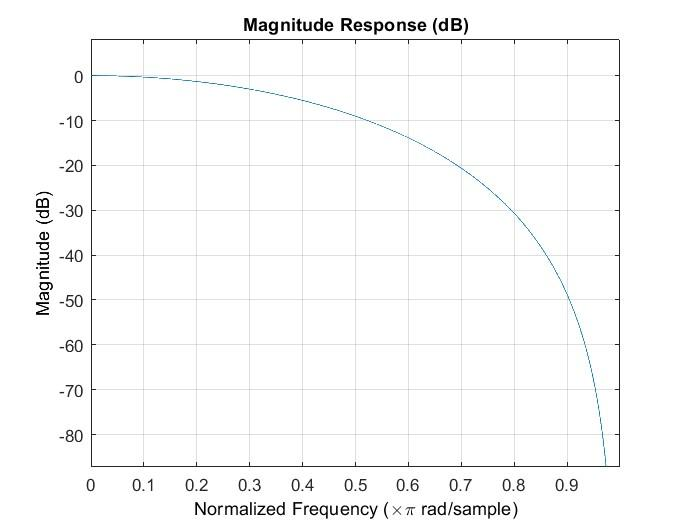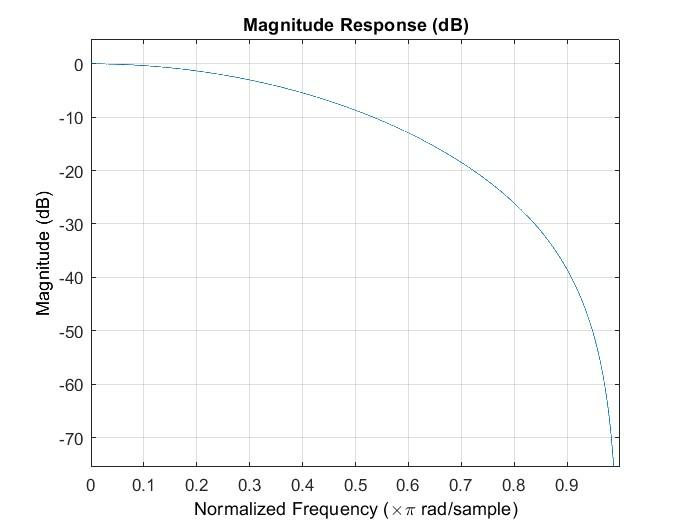

### Zadanie 2

figure;
b = [1 -0.5]; a = [1 -2];
stab22 = isstable(b, a)

stab22 = logical
   0


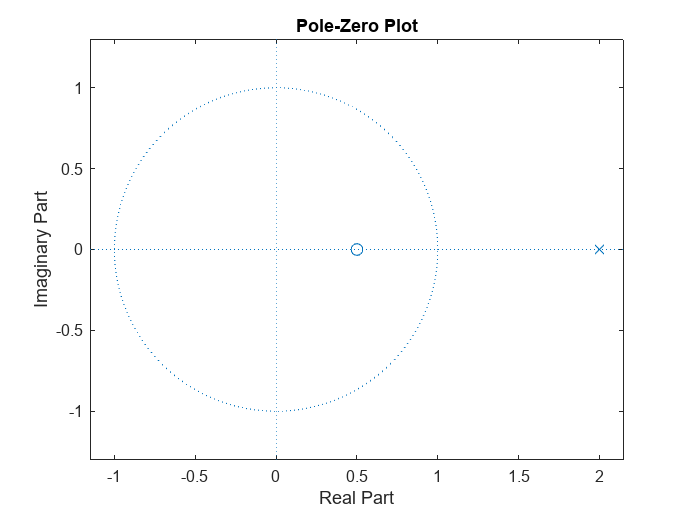

zplane(b, a);

Filtr jest niestabilny.

### Zadanie 3

figure;
b = [1 -0.1]; a = [-1 -0.1];
stab23 = isstable(b, a)

stab23 = logical
   1


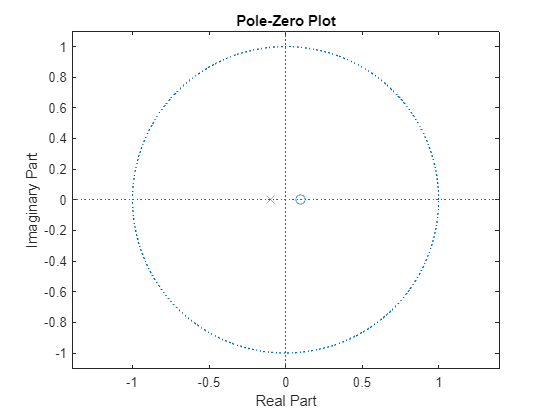

zplane(b, a);

Filtr jest stabilny.

### Zadanie 4

figure;
b = [0.9 -0.8]; a = [0.9 -0.8];
stab24 = isstable(b, a)

stab24 = logical
   1


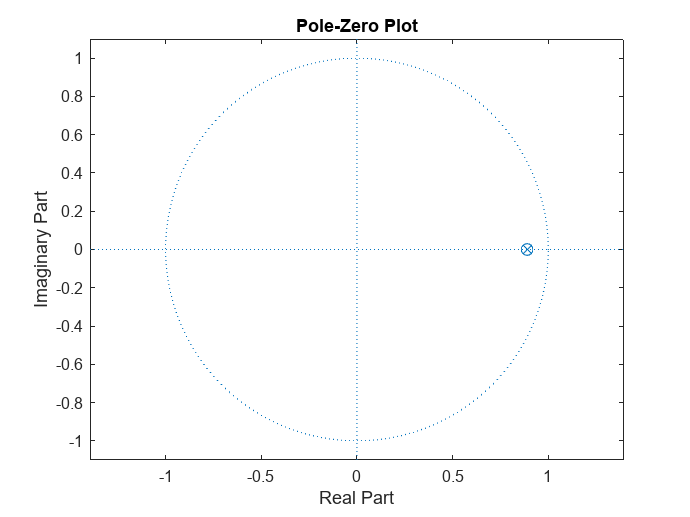

zplane(b, a);

Filtr jest stabilny.

### Zadanie 5

figure;
b = [0.9 -0.8 1 1]; a = [-0.9 -0.8 -1];
stab25 = isstable(b, a)

stab25 = logical
   0


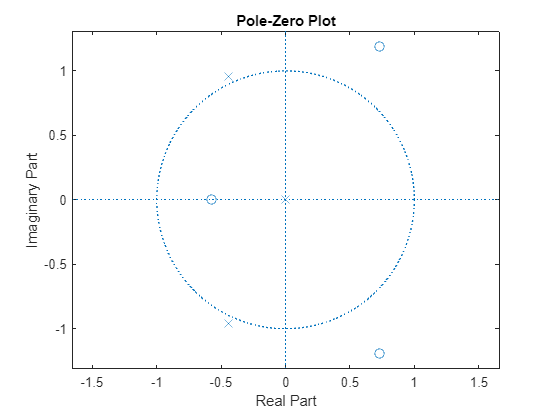

zplane(b, a);

Filtr jest niestabilny.

### Zadanie 6

figure;
m = [0 0 1 1 1 0 1 1 0 0];
f = [0 0.1 0.2 0.3 0.4 0.5 0.7 0.8 0.9 1];
[b,a] = yulewalk(10,f,m);
Stab26 = isstable(b, a)

Stab26 = logical
   1


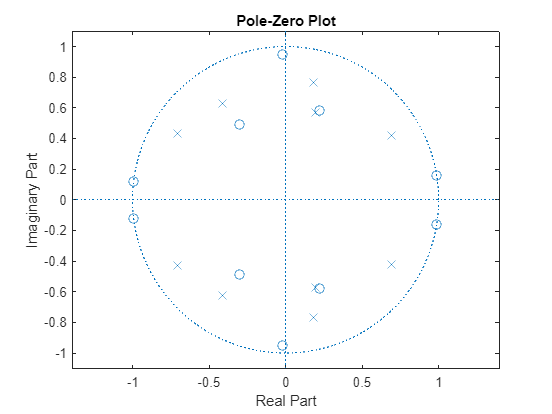

zplane(b, a);

Filtr jest stabilny.

### Zadanie 7

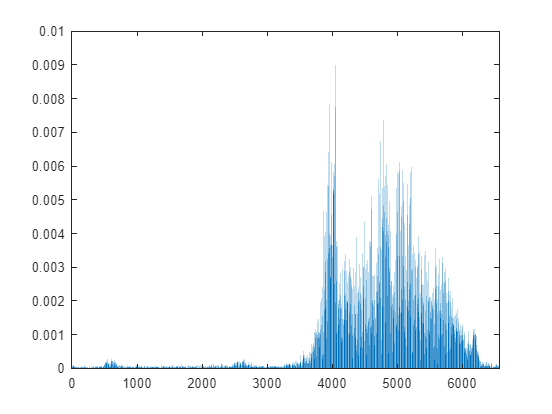

figure;
load chirp

t = (0:length(y)-1)/Fs;

xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]);

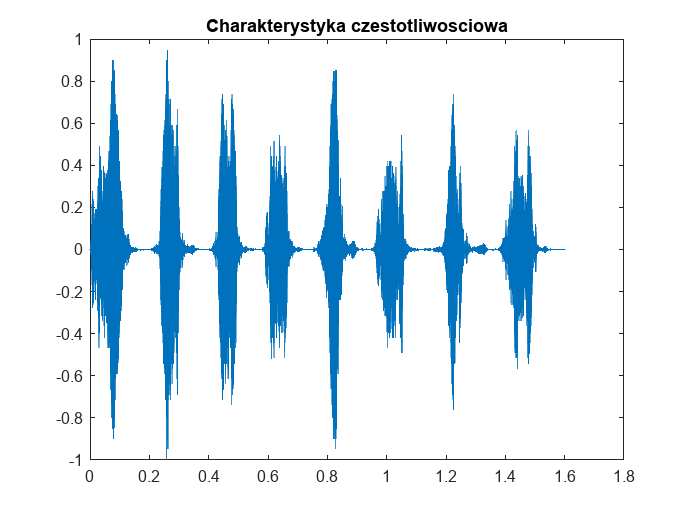

plot(t,y);
title('Sygnal w dziedzinie czasu');

[b,a] = maxflat(4, 1, 0.3);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

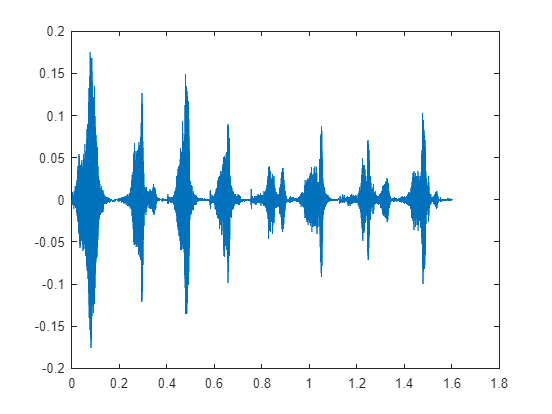

out = filter(b,a,y);

plot(t, out);

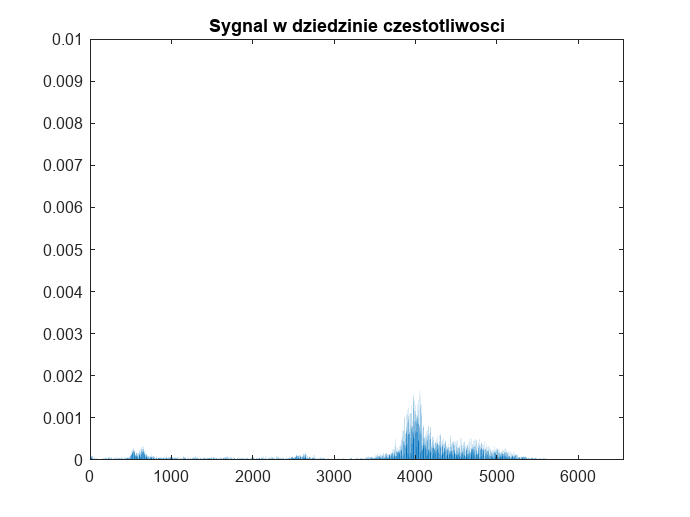

xfft=abs(fft(out));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

### Zadanie 8

figure;
load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

plot(t,y);
title('Sygnal w dziedzinie czasu');

m = [0 0 0 0 0 1 1 1 1 1];
f = [0 0.1 0.2 0.3 0.4 0.5 0.7 0.8 0.9 1];
[b,a] = yulewalk(10,f,m);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

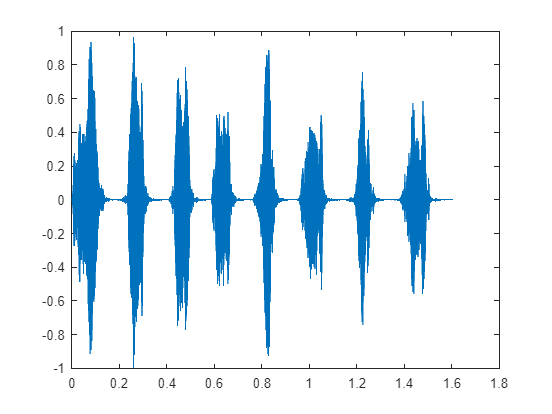


out = filter(b,a,y);
plot(t, out);

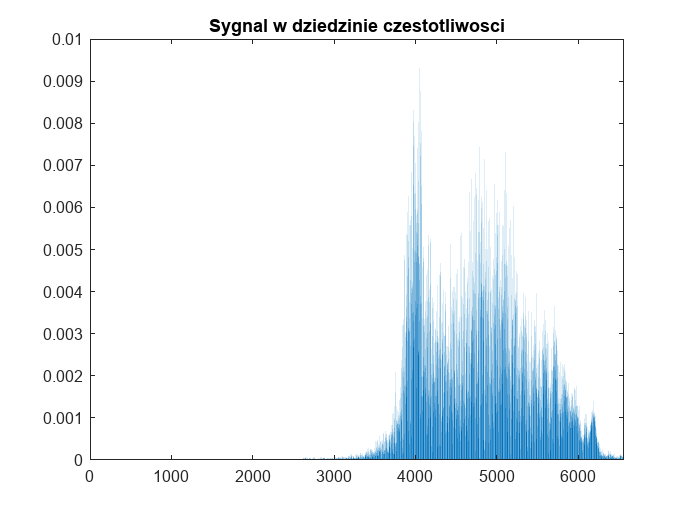

xfft=abs(fft(out));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

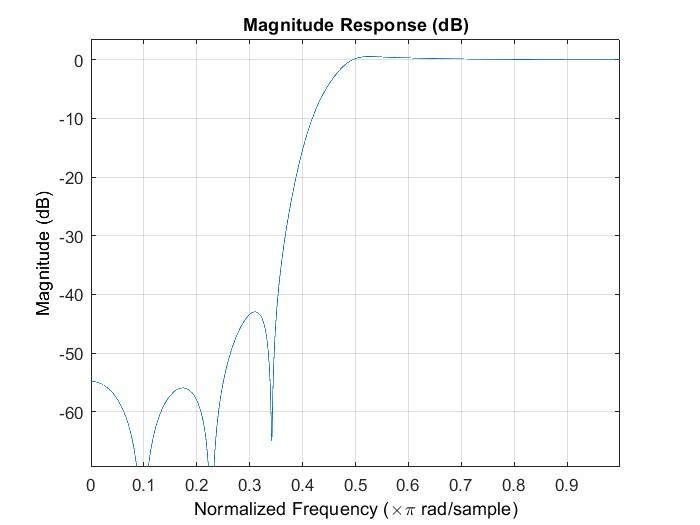

### Zadanie 9

load chirp
figure;
t = (0:length(y)-1)/Fs;
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

plot(t,y)
title('Sygnal w dziedzinie czasu');

b = [0.9 -0.8 1 1];
a = [-0.9 -0.8 -1];
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

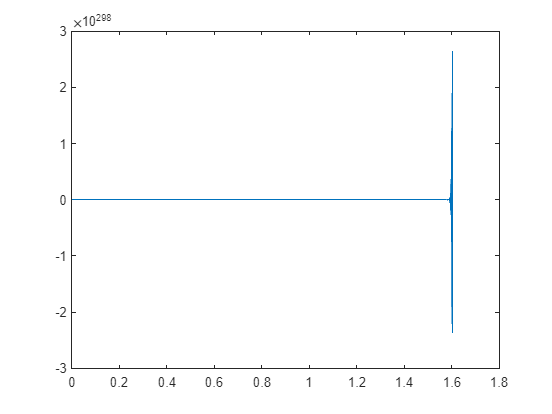


out = filter(b,a,y);
plot(t, out);

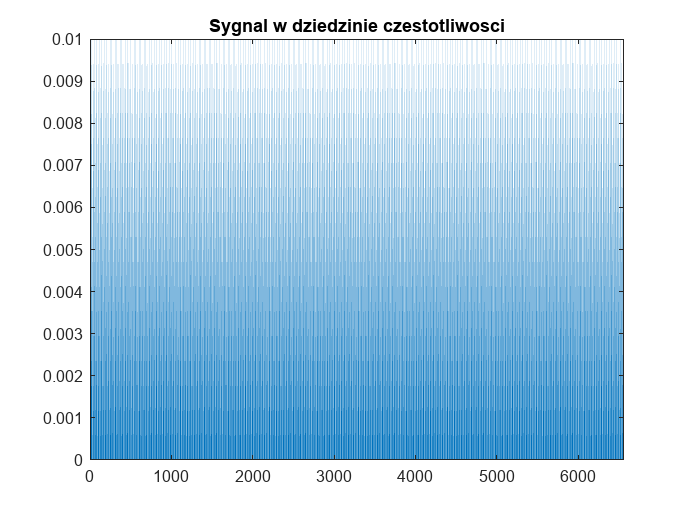

xfft=abs(fft(out));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

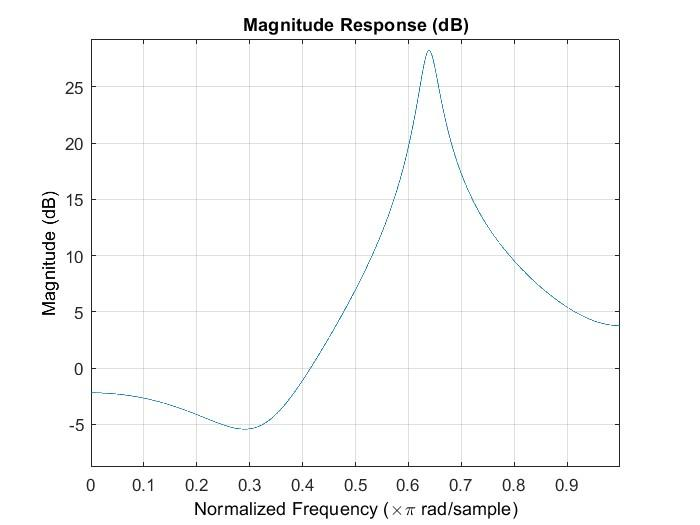

### Zadanie 10

load chirp
figure;
t = (0:length(y)-1)/Fs;
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

plot(t,y)
title('Sygnal w dziedzinie czasu');

[n, Wn] = buttord([2000 3000]/5000, [500 4500]/5000,1,60);
[b,a] = butter(n,Wn);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

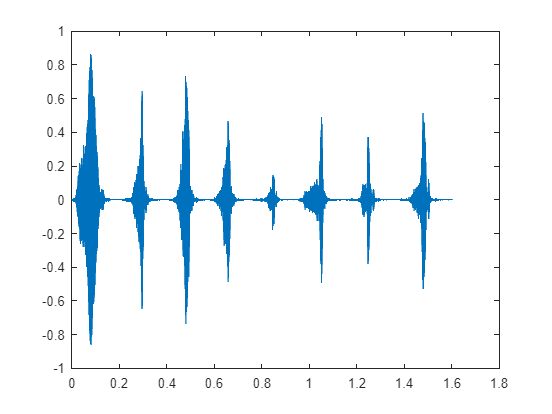


out = filter(b,a,y);
plot(t, out);

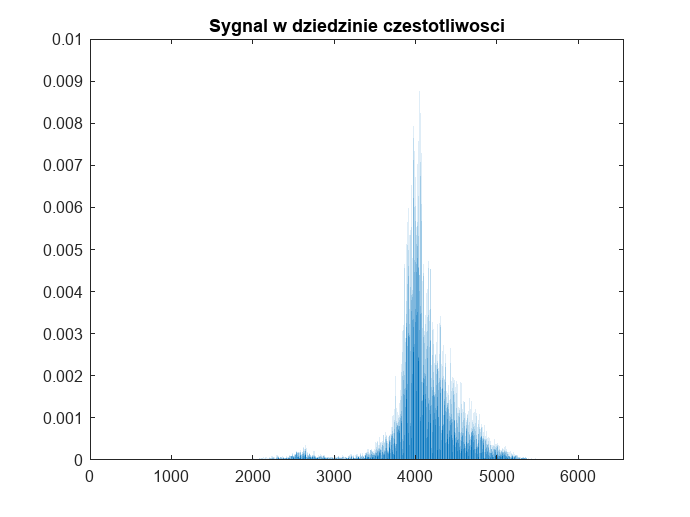

xfft=abs(fft(out));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

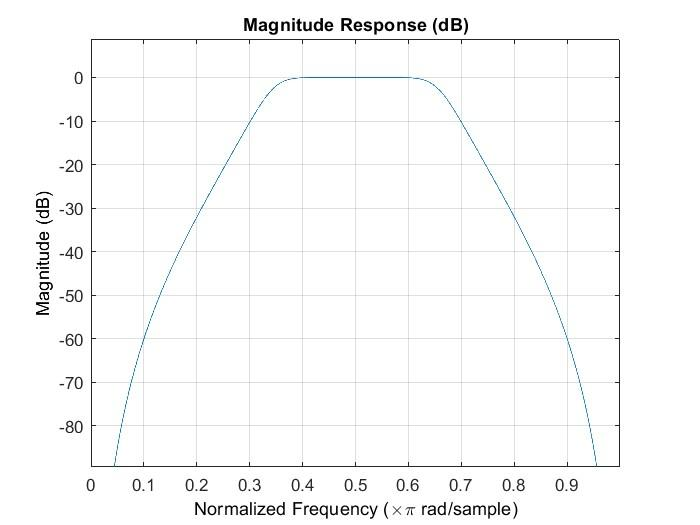

### Zadanie 11

load chirp
figure;
t = (0:length(y)-1)/Fs;
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

plot(t,y)
title('Sygnal w dziedzinie czasu');

[n, Wn] = buttord([2000 3000]/5000, [1800 3200]/5000,1,60);
[b,a] = butter(n,Wn);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

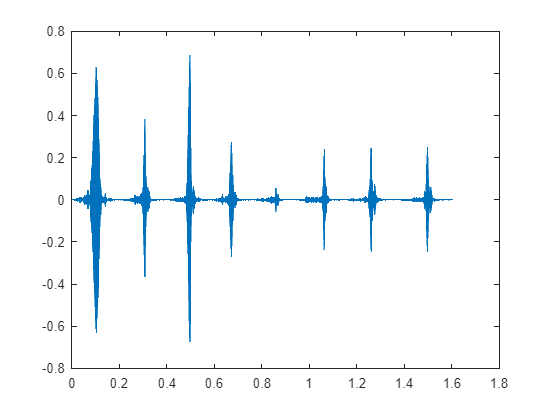


out = filter(b,a,y);
plot(t, out);

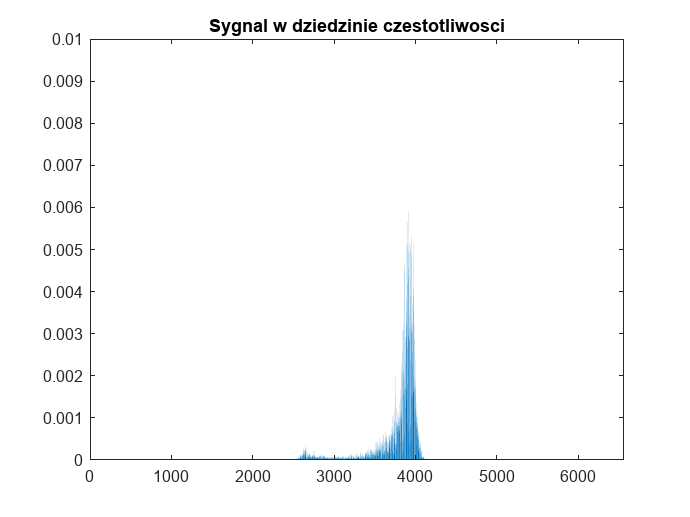

xfft=abs(fft(out));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

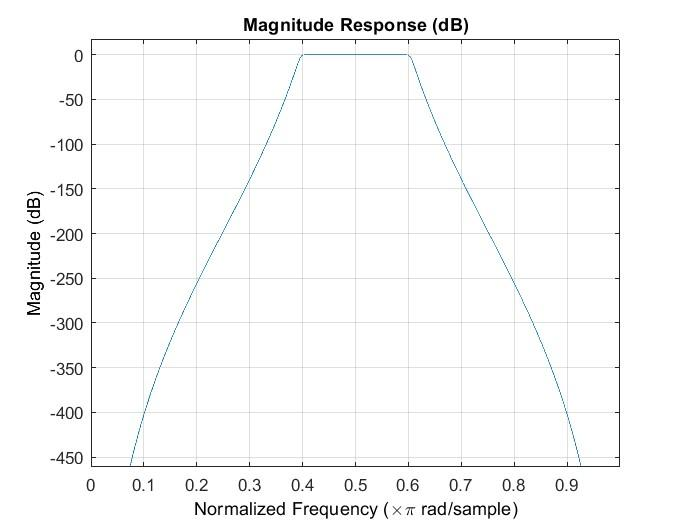

### Zadanie 12

load chirp
figure;
t = (0:length(y)-1)/Fs;
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

plot(t,y)
title('Sygnal w dziedzinie czasu');

[n, Wn] = ellipord([2200 2700]/5000, [2000 2900]/5000,1,60);
[b,a] = ellip(n, 1, 60, Wn);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

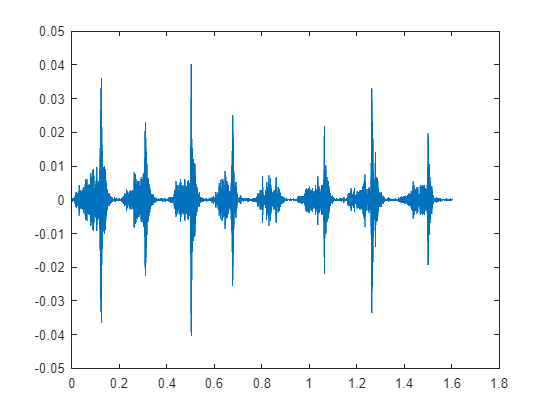


out = filter(b,a,y);
plot(t, out);

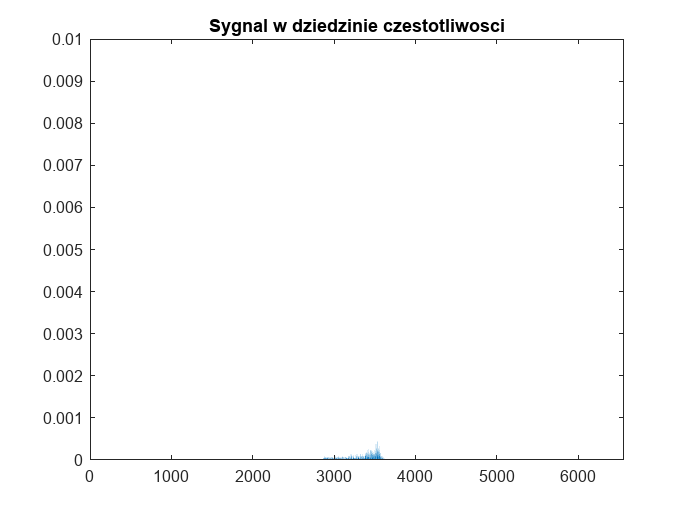

xfft=abs(fft(out));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

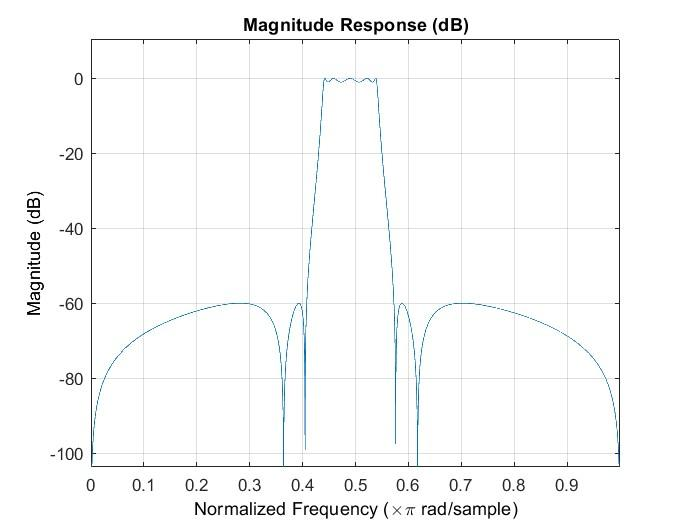

### Zadanie 13

load chirp
figure;
t = (0:length(y)-1)/Fs;
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

plot(t,y)
title('Sygnal w dziedzinie czasu');

[n, Wn] = ellipord([1000 4000]/5000, [900 4100]/5000,1,60);
[b,a] = ellip(n, 1, 60, Wn);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

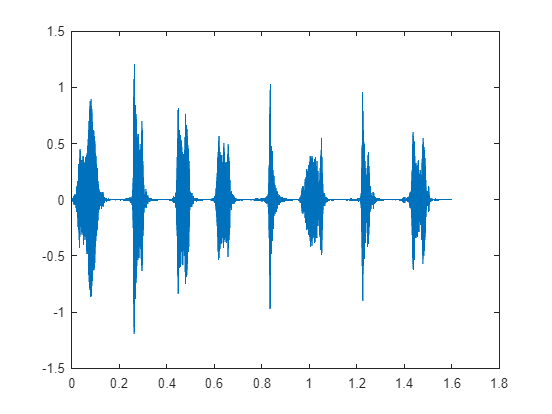


out = filter(b,a,y);
plot(t, out);

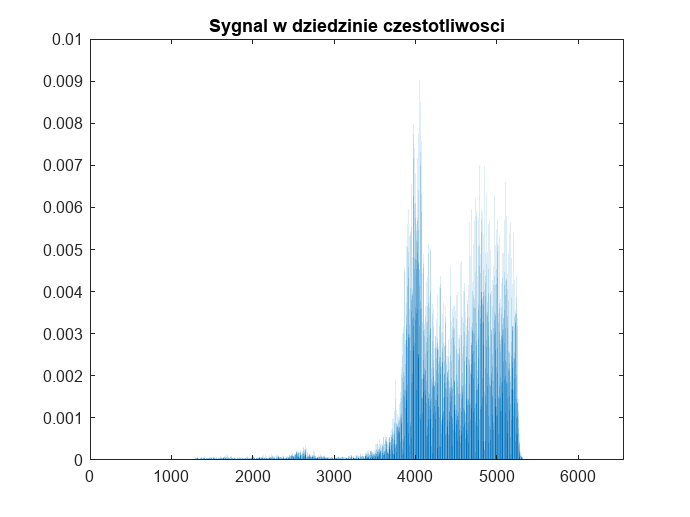

xfft=abs(fft(out));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

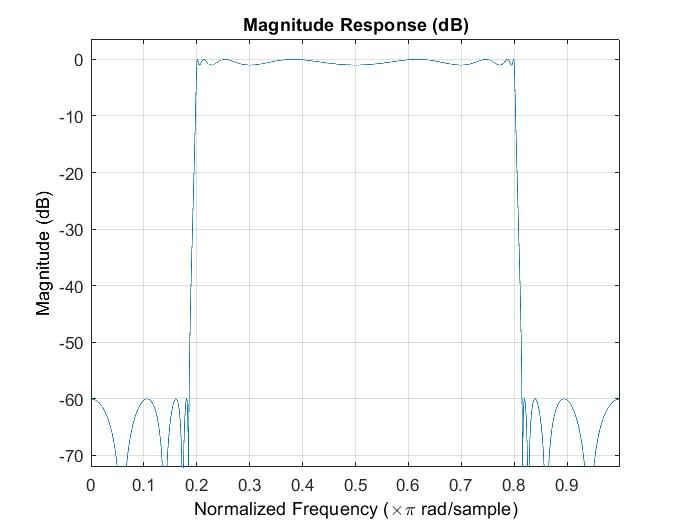

### Zadanie 14

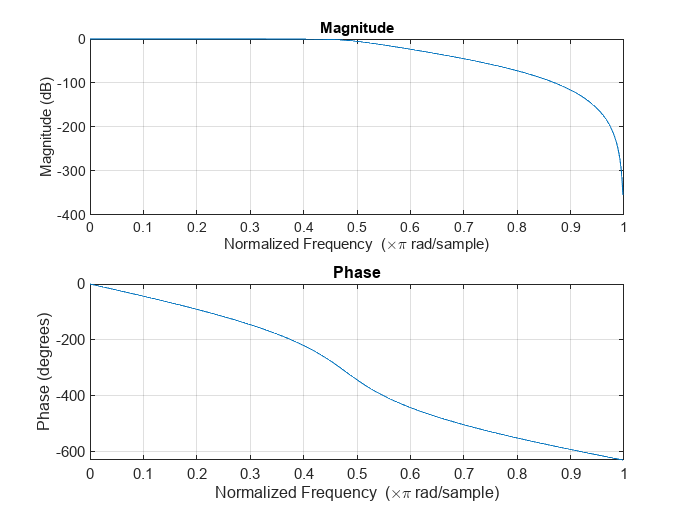

load chirp
[zhi,phi,khi] = butter(7,0.48,'low');
soslo = zp2sos(zhi,phi,khi);
freqz(soslo)


figure;
t = (0:length(y)-1)/Fs;
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

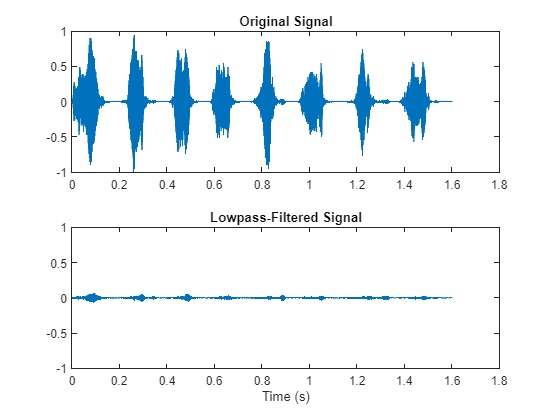


outlo = sosfilt(soslo,y);
subplot(2,1,1)
plot(t,y)
title('Original Signal')
ys = ylim;

subplot(2,1,2)
plot(t,outlo)
title('Lowpass-Filtered Signal')
xlabel('Time (s)')
ylim(ys)

### Zadanie 15

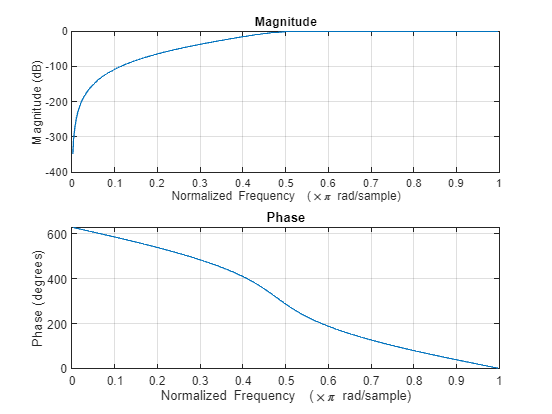

load chirp
[zhi,phi,khi] = butter(7,0.48,'high');
soshi = zp2sos(zhi,phi,khi);
freqz(soshi)


figure;
t = (0:length(y)-1)/Fs;
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]);

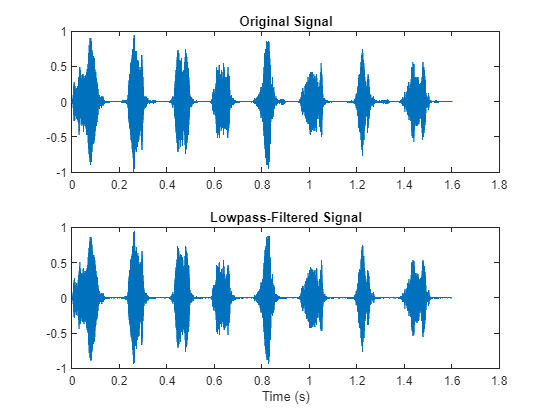


outhi = sosfilt(soshi,y);
subplot(2,1,1)
plot(t,y)
title('Original Signal')
ys = ylim;

subplot(2,1,2)
plot(t,outhi)
title('Lowpass-Filtered Signal')
xlabel('Time (s)')
ylim(ys)